# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Newstru\Newstru1\RawData'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 5;
Deci.Proceed            = true;  
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Newstru\Newstru1\ProcessedData'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {9};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {10};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};   
    Deci.DT.Locks      = [14 30 50];
    Deci.DT.Toi        = [-2 3]; 
    
    Deci.DT.Block.Start = {11};
    Deci.DT.Block.End = {12};
    Deci.DT.Block.Markers = [];

## 2. PreProcessing Steps

Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.

## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5]; 
Deci.Art.bpf = [1 80];

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =true;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3]; 
Deci.Analysis.DownSample = 500;

#### Time-Frequency Analysis

Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 

Deci.Analysis.Var =false;
Deci.Analysis.Clean = true;

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Plot.Conditions = {[20 31 51] [21 31 51] [23 31 51] [24 31 51] [20 31 52] [21 31 52] [23 31 52] [24 31 52] ...
                            [20 32 51] [21 32 51] [23 32 51] [24 32 51] [20 32 52] [21 32 52] [23 32 52] [24 32 52]};
    Deci.Plot.Var = false;
    Deci.Plot.GA = true;

#### Math

Deci.Plot.Math.Form = {'[x4+x2]/2','[x7+x5]/2','[x2+x5]/2','[x4+x7]/2' '[x17-x18]' '[x19-x20]'...
                       '[x2-x4]','[x5-x7]','[x4-x7]','[x2-x5]' '[[x2+x3+x4+x13+x14+x15]/6]' '[[x5+x6+x7+x10+x11+x12]/6]' '[x27-x28]' ...
                       '[x4+x2+x12+x10]/2','[x7+x5+x15+x13]/2','[x2+x5+x10+x13]/2','[x4+x7+x12+x15]/2' '[x2+x3+x4]/3' '[x13+x14+x15]/3' '[x5+x6+x7]/3' '[x10+x11+x12]/3'  ...
                        '[x2+x10]' '[x3+x11]/2' '[x4+x12]/2' '[x5+x13]/2' '[x6+x14]/2' '[x7+x15]/2'};   
%Deci.Plot.Math.Type = 0;


#### Conditions

Deci.Plot.Draw = {[2 4 5 7] [17:18] [19:20] [21:22] [23:24] [25] [26] [27:28] [29] [30 31] [32 33] [34:37] [38:43] [2:7 10:15]};
Deci.Plot.Title = {'All Opt 10 trials' 'Opt Prediction Error' 'Opt Valence Signals' 'Valence-independent Prediction Error' 'PE-independent Valence Signals' ...
                    'Valence-Dependent Prediction Error' 'PE-dependent Valence Signal' 'Expectation Signals' 'Expectation Subtraction' 'Prediction Error' 'Valence Signals' 'Expectations Signals' 'All Fdb Trials' 'All Resp Trials'};
Deci.Plot.Subtitle = {{'+R' '+P' '-R' '-P'} {'+' '-'} {'R' 'P'} {'+R - +P' '-R - -P'} {'+P - -P' '+R - -R'} {'+ - -'} {'R - P'} {'[BTEOpt+WTEWor]' '[WTEOpt+BTEWor]'} {'[BTEOpt+WTEWor]-[WTEOpt+BTEWor]'} ...
                    {'+' '-'} {'R' 'P'} {'Opt+' 'Wte-' 'Wte+' 'Opt-'} {'+R' '+0' '+P' '-R' '-0' '-P'} {'O_+R' 'O_+0' 'O_+P' 'O_-R' 'O_-0' 'O_-P' 'W_+R' 'W_+0' 'W_+P' 'W_-R' 'W_-0' 'W_-P'}};
Deci.Plot.Figures = [true false false false false false false false false  false  false false  false  false];

#### Time-Frequency

%Deci.Plot.Freq.Foi = [];
Deci.Plot.Freq.Foi = [4 8];
Deci.Plot.Freq.Toi = [];
Deci.Plot.Freq.Channel = {'FCz'};
Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Plot.Freq.Bsl = [-.5 0];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxabs';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

Deci.Plot.Freq.Topo =0;
Deci.Plot.Freq.Square =1;

Deci.Plot.Freq.Wires.avg =  'freq';

Deci.Plot.CFC.chanlow =  {'FCz'};
Deci.Plot.CFC.chanhigh =  [{'F5' 'FCz'  'F6' }];
Deci.Plot.CFC.latencyhigh = [0 1]; %no implementation yet to check for edge artifacts so be careful
Deci.Plot.CFC.latencylow = [0 1];
Deci.Plot.CFC.freqhigh = 'beta';
Deci.Plot.CFC.freqlow = 'theta';

Deci.Plot.CFC.timebin = 5;
Deci.Plot.CFC.methods = {'mi','plv'};  % can only currently handle '' or 'mi'(pac)

Deci.Plot.CFC.Topo = 1;
Deci.Plot.CFC.Square = 1;
Deci.Plot.CFC.Hist = 1;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest


#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1:16] [1:16]};
Deci.Plot.Behv.Acc.Subtotal = {[1:8] [9:16]};
Deci.Plot.Behv.Acc.Title = ['All Trials Percent'];
Deci.Plot.Behv.Acc.Subtitle = {'Opt Percent' 'Wst Percent'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  true;

Deci.Plot.Behv.RT.Draw = {[1:8] [9:16]};
Deci.Plot.Behv.RT.Title = ['All Trials RT'];
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =false;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = false;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = true;

## ** 6. Run**

Channel FCz of 1
Elapsed time is 0.859379 seconds.
Channel FCz of 1
Elapsed time is 0.748545 seconds.
Channel FCz of 1
Elapsed time is 0.785185 seconds.
Channel FCz of 1
Elapsed time is 0.732767 seconds.
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds


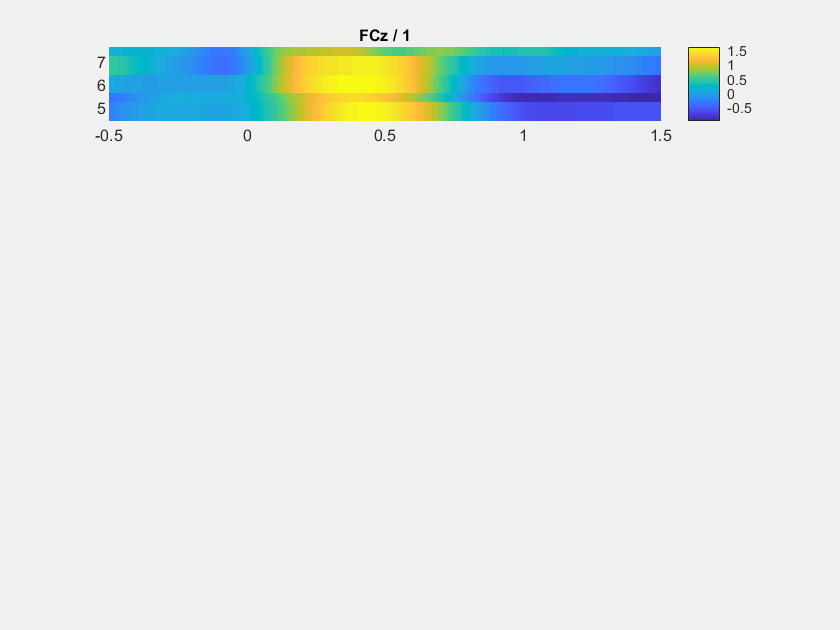

the call to "ft_singleplotTFR" took 0 seconds



Deci_Backend(Deci);